# Response Amplitude Operator Calculation

Author: M. Noyce

This program calculate the heave ROA of several data sets and plots the results at different frequencies to show the frequency response.

Requirements: Wave Tank Testing Data 

## Read in wave tank testing data

%Specify directories
dataDir = "C:\Users\uctsh\Documents\MATLAB\WaveTankData";

%Read Data into table 
%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["Time","Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

%Read in each dataset
WaveTable_2Hz = readtable("2Hz_20mm_reg.csv", opts);
WaveTable_1_5Hz = readtable("1_5Hz_20mm_reg.csv", opts);
WaveTable_1Hz = readtable("1Hz_20mm_reg.csv", opts);
WaveTable_0_75Hz = readtable("075Hz_20mm_reg.csv", opts);
WaveTable_0_5Hz = readtable("05Hz_20mm_reg.csv", opts);


## Calculate Wave Parameters

%Sample Rate
Fs = 100;



%Truncate Arrays to remove start and end of testing sequence
%Read in each dataset
%Size 250 seconds

WaveTable_2Hz = WaveTable_2Hz(400*Fs:Fs*650, :);
WaveTable_1_5Hz = WaveTable_1_5Hz(Fs*350:Fs*600, :);
WaveTable_1Hz = WaveTable_1Hz(Fs*300:Fs*550, :);
WaveTable_0_75Hz = WaveTable_0_75Hz(Fs*250:Fs*500, :);
WaveTable_0_5Hz = WaveTable_0_5Hz(Fs*200:Fs*450, :);

%Concatenate All Heave Values into single table
WaveTableHeaveAll = [WaveTable_0_5Hz.Heave WaveTable_0_75Hz.Heave WaveTable_1Hz.Heave WaveTable_1_5Hz.Heave WaveTable_2Hz.Heave];

%Preprocess Vertical Acceleration Signal: Each Time Series

% Scale 
WaveTableHeaveAll = ( WaveTableHeaveAll / 16384 ) * 9.81 - ( 9.81 * 16384 ); 
%Detrend 
WaveTableHeaveAll = detrend(WaveTableHeaveAll);
%Lowpass filter 
WaveTableHeaveAll = lowpass(WaveTableHeaveAll, 10, 100);


time = 0:0.01:((height(WaveTableHeaveAll)-1)/Fs)

time =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


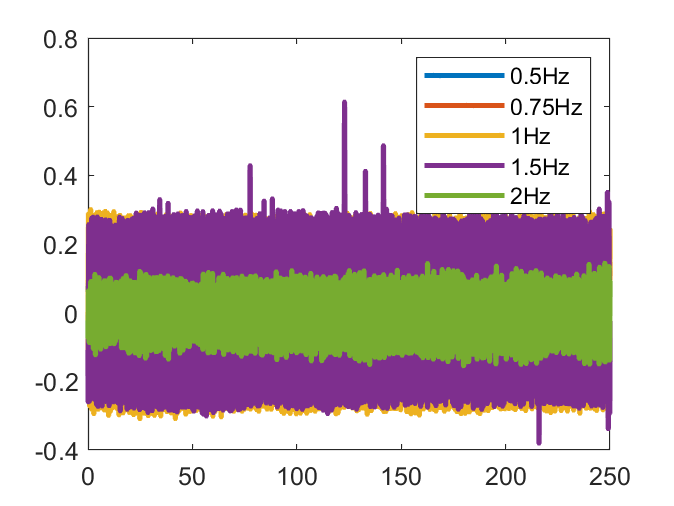


plot(time, WaveTableHeaveAll, "LineWidth", 2);
legend("0.5Hz", "0.75Hz", "1Hz", "1.5Hz", "2Hz");


%Double integration in the frequency domain
f1 = 0.30; %Lower corner frequency for half cosine taper
f2 = 0.40; %Upper frequency for half cosine taper
fc = 4; 

%VertAccArray = HeaveAccArray;

Nfft = length(WaveTableHeaveAll); %use HeaveAccArray if heave only

%frequency array 
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -50.0000
  -49.9960
  -49.9920
  -49.9880
  -49.9840
  -49.9800
  -49.9760
  -49.9720
  -49.9680
  -49.9640


N = size(f, 1); 


%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);


for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 && f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1)))*(-1/(2*pi*f(i)).^2);
        end
            if f(i) > f2 && f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)).^2; 
            end
end


sec_10 = Fs*10; 
elevArray = zeros(length(WaveTableHeaveAll)-2*sec_10+1, width(WaveTableHeaveAll));

for i = 1:width(WaveTableHeaveAll)

    %Tranform to the frequency domain 
    y = fft(WaveTableHeaveAll(:, i));
    y = fftshift(y);
    
    %Acceleration .* Rf
    elevFFT = y.*Rf; 
    
    %Elevation 
    elev = ifft(fftshift(elevFFT)); 
    
    %Remove 30s from each side 
    elev = detrend(real(elev));
    elev = elev(sec10:(end-sec_10));
    elevArray(:, i) = elev*2;
    
end



%Time Array for plots
time = 0:0.01:((length(elevArray)-1)/Fs)

time =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


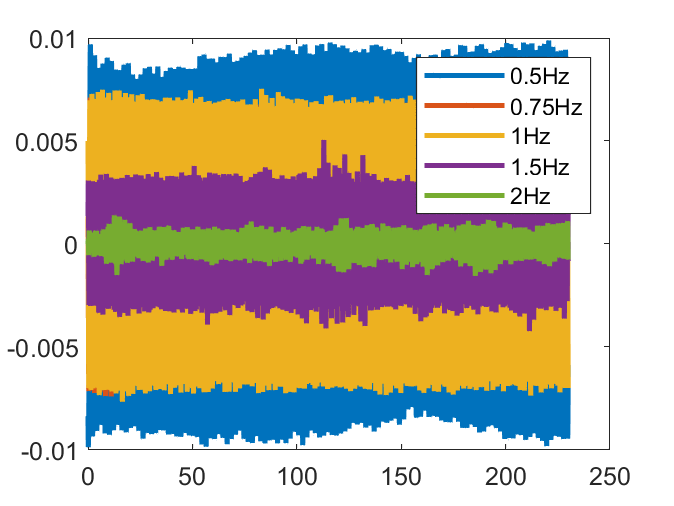


plot(time, elevArray, "LineWidth", 2);
legend("0.5Hz", "0.75Hz", "1Hz", "1.5Hz", "2Hz");


%Extract Wave Parameters
%Welch Method
%Window = 5 * 60 * 100; 
%segmentLength = 60*5*100;
%nooverlap = segmentLength/2; 

%Calculate PSD Estimate for each displacement series 
waveParamArray = zeros(width(WaveTableHeaveAll), 2);

for k = 1:width(WaveTableHeaveAll)
    
    %PSD Estimate 
    [pxx, f, pxxc] = pwelch(elevArray(:, k), [], [], [], 100, "onesided", 'ConfidenceLevel', 0.80); 

    %Scaling coefficent
    pxx = pxx;
    pxxc = pxxc;

    %Extraction of wave parameters
    m=length(pxx);

    %number of subintervals
    m=m-1;

    %length of the subinterval
    Ax=(f(m+1)-f(1))/m;

    %Integral I1 m0=int{E(f)df} I1
    s=0;
    s_lower = 0; 
    s_upper = 0;
    
    for i=2:m
     s=s+pxx(i); %sum(2,m) f(xi)
     s_lower=s_lower+pxxc(i, 1);
     s_upper = s_upper+pxxc(i, 2);
    end
    
    m0=0.5*Ax*(pxx(1)+2*s +pxx(m+1));
    m0_lower = 0.5*Ax*(pxxc(1, 1)+2*s_lower +pxxc(m+1, 1));
    m0_upper = 0.5*Ax*(pxxc(1, 2)+2*s_upper +pxxc(m+1, 2));
    
    %Integral I2 m1=int{f*E(f)df} I2
    s=0;
    s_lower = 0;
    s_upper = 0;
    
    %f=f*E(f)=f*mW
    for i=2:m
     s=s+f(i)*pxx(i);
     s_lower = s_lower + f(i)*pxxc(i, 1); 
     s_upper = s_upper + f(i)*pxxc(i, 2); 
    end
    
    m1= 0.5*Ax*(f(1)*pxx(1)+2*s+f(m+1)*pxx(m+1));
    m1_lower = 0.5*Ax*(f(1)*pxxc(1, 1)+2*s_lower+f(m+1)*pxxc(m+1, 1));
    m1_upper = 0.5*Ax*(f(1)*pxxc(1, 2)+2*s_upper+f(m+1)*pxxc(m+1, 2));
    
    Hm0 = 4*sqrt(m0);
    Tm01 = m0/m1; 
    Hm0_lower = 4*sqrt(m0_lower);
    Hm0_upper = 4*sqrt(m0_upper);

    %Add Parameters to Array 
    waveParamArray(k, 1) = Hm0;
    waveParamArray(k, 2) = Tm01;
    waveParamArray(k, 3) = Hm0_upper;
    waveParamArray(k, 4) = Hm0_lower;

     
end 


## Plot RAO 

%Calculate wavelength 
g = 9.812; 

waveParamArray(5, :) = [];
L = ((g.*flip(waveParamArray(:, 2)).^2) ./ 2*pi)./100; 

D = 0.30; 
nonD = L./D;

%Measured Hm0 values from calibration probes 



%Hm0 
Hm0 = flip(waveParamArray(:, 1))./[0.020 ; 0.020 ; 0.020; 0.032]

Hm0 =     0.4280
    0.9731
    0.8923
    0.8065


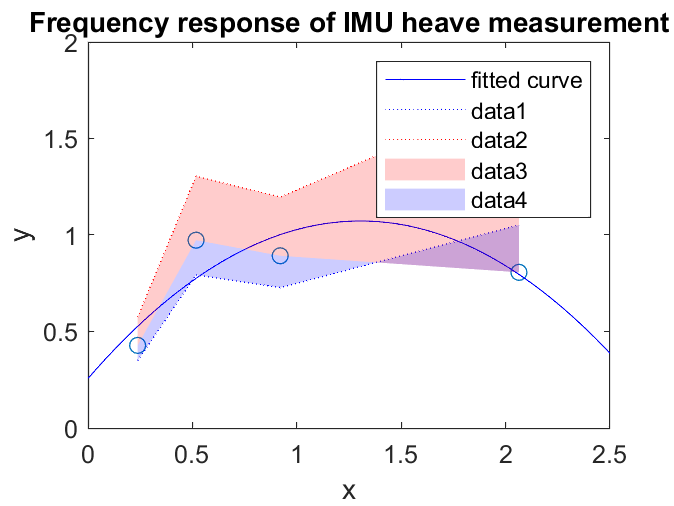

%Upper
Hm0Upper = flip(waveParamArray(:, 3))./0.02; 

%Lower
Hm0Lower = flip(waveParamArray(:, 4))./0.02; 

%Fit with polynomial
Hm0Fit = fit(nonD, Hm0, 'poly2'); 

%Plot Hm0 
plot(nonD, Hm0, 'o');
title("Frequency response of IMU heave measurement")
xlabel("\lambda/D")
ylabel("a/a_H")
hold on
plot(Hm0Fit, "b");
xlim([0, 2.5]);
hold on 
plot(nonD, Hm0Lower, "LineWidth", 0.5, "LineStyle", ":", "Color", "blue"); 
hold on
plot(nonD, Hm0Upper, "LineWidth", 0.5, "LineStyle", ":", "Color", "red"); 
hold on 
patch([nonD; flipud(nonD)], [Hm0Upper; flipud(Hm0)]', 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'LineStyle', 'none');
hold on
patch([nonD; flipud(nonD)], [Hm0; flipud(Hm0Lower)]', 'b', 'FaceAlpha',0.2, 'EdgeColor', 'none', 'LineStyle', 'none')  
hold off